## Inverted Pendulum Animation

The following lines of code are unnecessary but interesting to view an animation of the inverted pendulum model

simulinkModel = "motomatic_pend_V2_GA";
t = 10;
Ka     = 5.1793;     % Power Amplifier
N      = 8.1;        % Speed Reduction Factor
Km     = 22.289;     % Motor gain [rad/s/V]
Km_lin = 19.763;     % Linearized motor gain [rad/s/V]
tau_m  = .2740;      % Motor time constant [s]
Kp     = 4.90379;    % Position Feedback Gain
Kt     = .1429;
vmo    = 0.66;       % Voltage to hold pendulum at 90 degrees [V]
g      = 9.81;       % gravitational acceleration [m/s/s]
%Defining physical parameters of the pendulum
L = 11;      % Pendulum rod length [in]
L = L/39.37; % Pendulum rod length [m]
m = 28/1000; % Bob mass [kg]
physParam = [m, L, g, vmo, N];
%The next line will define the intial condition of the pendulum
th_init = deg2rad(110);

simout = sim(simulinkModel, t);
xpend = L*sin(simout.X(:,1));
ypend = L*cos(simout.X(:,1));
fps = 60;
t = 0:1/fps:max(simout.tout);
xpend = interp1(simout.tout,xpend,t);
ypend = interp1(simout.tout,ypend,t);
origin = zeros(1,length(xpend));

The next lines of code create the animation.

pendGif = figure;
pendGif.Visible = 'on';
ax = axes;
axis([-.3 .3 -.2 .4]);xticks([-3:.1:.3])
hold on;
traject = animatedline('color','r','MaximumNumPoints', 15,'LineWidth',2);
arm = plot([origin xpend],[origin ypend],'b-','LineWidth',3);
p = plot(xpend,ypend,'ko', 'MarkerFaceColor','k','MarkerSize',30);
h = fill([-1 1 1 -1],[-1 -1 L*cos(110*pi/180)-.01 L*cos(110*pi/180)-.01],[.5 .5 .5]);
ax = gca;
ax.FontSize = 12;
set(gcf,'position',[0 0 600 600]);
xlabel('Horizontal Position [m]','Interpreter','Latex','FontSize',16);
ylabel('Vertical Position [m]','Interpreter','Latex','FontSize',16);
grid on; box on;
hold off

The following `for` loop is used to refresh the plot for every tick of time defined earlier by the desired fps.

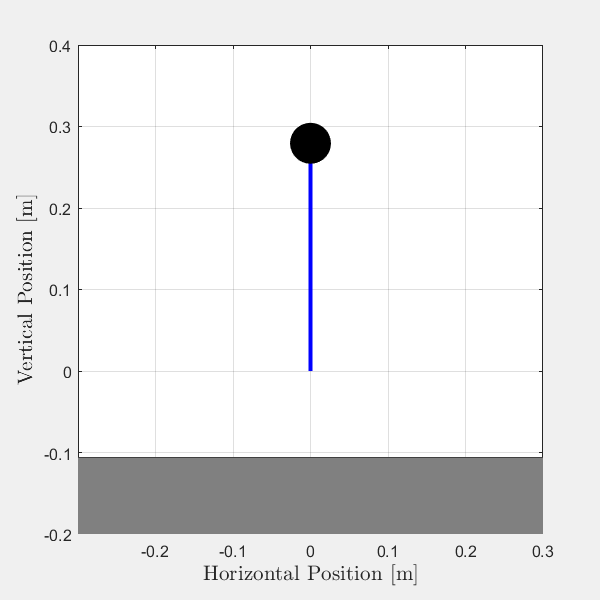

for n = 1:length(t)
    p.XData = xpend(n);
    p.YData = ypend(n);
    arm.XData = [origin(n) xpend(n)];
    arm.YData = [origin(n) ypend(n)];
   
    addpoints(traject,xpend(n),ypend(n));
    drawnow
    
    frame = getframe(pendGif);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    
    if n == 1
        imwrite(imind,cm,'pend.gif','gif','LoopCount', inf,'DelayTime',1/fps);
    elseif n == length(t)
        imwrite(imind,cm,'pend.gif','gif','WriteMode','append','DelayTime',5/fps);
    else
        imwrite(imind,cm,'pend.gif','gif','WriteMode','append','DelayTime',1/fps);
    end
end